DMP code from Sidiropoulos, Antonis, Dimitrios Papageorgiou, and Zoe Doulgeri. "[A novel framework for generalizing dynamic movement primitives under kinematic constraints.](https://link.springer.com/article/10.1007/s10514-022-10067-4)" *Autonomous Robots* 47.1 (2023): 37-50. Available at: [https://github.com/Slifer64/novel-DMP-constraints](https://github.com/Slifer64/novel-DMP-constraints)

## Load configuration and settings

clearvars; clc; close all;

addpath(genpath('..\libs\novel-DMP-constraints'));

% Define linear system to generate data
A  = [-1 0; 0 -3];
B  = [1 0; 0 1];
x0 = [0.0;0.0];
x1 = [1.0;2.0];
t_end = 20;
dt = 0.01;

%% ======== Limits ==========
%            lower limit     upper limit
pos_lim = [[-1.2 -1.2]' [1.2 1.2]'];
vel_lim = repmat([-0.3 0.3], 2,1);  % lower and upper limit, same for all DoFs
accel_lim = repmat([-0.4 0.4], 2,1);

[u_training, x_training, time, cost_training] = analytic_solution(A,B,x0,x1,t_end,dt);

%% Load training data
Timed = time;
Pd_data = x_training;
Ts = dt;

## Training DMP

%% initialize and train GMP
train_method = 'LS';
N_kernels = 30;
kernels_std_scaling = 1.5;
n_dof = size(Pd_data,1);
gmp = GMP(n_dof, N_kernels, kernels_std_scaling);
tic
offline_train_mse = gmp.train(train_method, Timed/Timed(end), Pd_data);
offline_train_mse

offline_train_mse =     0.0871
    0.8753


toc

Elapsed time is 1.382832 seconds.



gmp.setScaleMethod( TrajScale_Prop(n_dof) );

taud = Timed(end);
yd0 = gmp.getYd(0); %Pd_data(1);
ygd = gmp.getYd(1); %Pd_data(end);

kt = 1.5; % temporal scaling
ks = diag([1 1 1]); % spatial scaling
tau = taud/kt;


## Generalize DMP to a new goal and respecting kinematic constraints

% Generalize to new goal yg
y0 = yd0 + 0;
yg = ygd + [0.7; -0.7];  

%% ======== Generate trajectories ==========

qp_solver_type = 0; % matlab-quadprog:0 , osqp:1, Goldfarb-Idnani: 2

%% --------- Proportional scaling -----------
%gmp2 = gmp.deepCopy();
%gmp2.setScaleMethod( TrajScale_Prop(n_dof) );
%[Time, P_data, dP_data, ddP_data] = getGMPTrajectory(gmp2, tau, y0, yg);

%% --------- Optimized DMP -> VEL -----------
%[Time, P_data, dP_data, ddP_data] = offlineGMPweightsOpt(gmp, tau, y0, yg, pos_lim, vel_lim, accel_lim, 0, 1, [], qp_solver_type); 

%% --------- Optimized DMP -> POS -----------
[Time, P_data, dP_data, ddP_data] = offlineGMPweightsOpt(gmp, tau, y0, yg, pos_lim, vel_lim, accel_lim, 1, 0, [], qp_solver_type);

n_points = 200

===> offline-GMP-weights optimization finished! Elaps time: 1774.041200 ms
DoF-1: Problem is infeasible. Or, for interior-point-convex, the step size was smaller than options.StepTolerance, but constraints were not satisfied.
DoF-2: Function converged to the solution x.


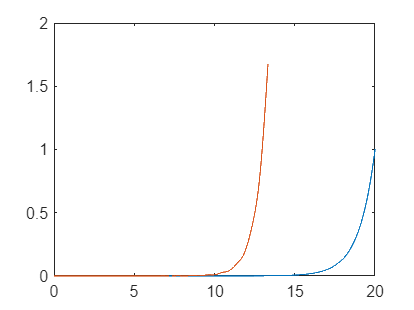


plot(Timed,Pd_data(1,:),Time, P_data(1,:))

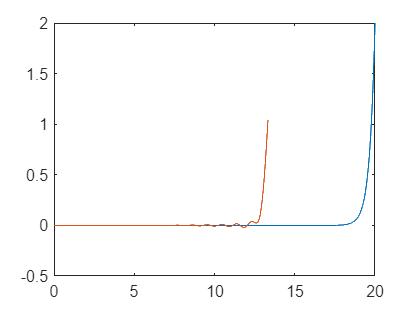

figure;
plot(Timed,Pd_data(2,:),Time, P_data(2,:))

## Auxiliar functions

function [u,x,t,cost] = analytic_solution(A,B,x0,x1,T,dt)
    syms t v
    
    W = int(expm(A*t)*(B*B')*expm(A'*t),[0,T]);
    % Check condition number for debug:
    % cond(vpa(W))
    z = -B'*expm(A'*(T-t))/W;
    
    % u(t) = -B'*e^[A(T-t)]*inv(W)*(e^[AT]*x0 - x1)
    u = z*(expm(A*T)*x0 - x1);
    
    f = int( expm(A*(t-v))*B*subs(u,t,v) , v, 0, t);
    
    % x'(t) = Ax(t) + f(t)
    x = matlabFunction(expm(A*t)*x0 + f);
    u = matlabFunction(u);
    
    cost = vpa((expm(A*T)*x0 - x1)'*inv(W')*(expm(A*T)*x0 - x1));
    
    t = 0:dt:T;
    x = x(t);
    u = u(t);
end 